tic;
disableTaps = true;
epsilon = 1e-5;

Centralized Power Flow Solution

varNames = ["bus_i", "type", "Pd", "Qd", ...
    "Gs", "Bs"];

addpath functions\

busData = [
  1    3    50    30.99    0    0    1    1    0    230    1    1.1    0.9;
  2    1    170   105.35   0    0    1    1    0    230    1    1.1    0.9;
  3    1    200   123.94   0    0    1    1    0    230    1    1.1    0.9;
  4    2    80    49.58    0    0    1    1    0    230    1    1.1    0.9;
];
N = size(busData, 1);

busTable = array2table(busData(:, 1:6));
busTable.Properties.VariableNames = varNames;
busTable.Pd = busTable.Pd/100;
busTable.Qd = busTable.Qd/100

busTable = 4×6 table
    bus_i    type    Pd       Qd      Gs    Bs
    _____    ____    ___    ______    __    __

      1       3      0.5    0.3099    0     0 
      2       1      1.7    1.0535    0     0 
      3       1        2    1.2394    0     0 
      4       2      0.8    0.4958    0     0 



branchData = [
    1    2    0.01008    0.0504    0.1025    250    250    250    0    0    1    -360    360;
    1    3    0.00744    0.0372    0.0775    250    250    250    0    0    1    -360    360;
    2    4    0.00744    0.0372    0.0775    250    250    250    0    0    1    -360    360;
    3    4    0.01272    0.0636    0.1275    250    250    250    0    0    1    -360    360;
    ];
numBranch = size(branchData, 1);

branchTable = array2table(branchData(:, 1:5));
varNamesBranchData = ["fbus", "tbus", "R", "X", "B"];
branchTable.Properties.VariableNames = varNamesBranchData

branchTable = 4×5 table
    fbus    tbus       R         X         B   
    ____    ____    _______    ______    ______

     1       2      0.01008    0.0504    0.1025
     1       3      0.00744    0.0372    0.0775
     2       4      0.00744    0.0372    0.0775
     3       4      0.01272    0.0636    0.1275



[ybus, BMatrix, b, A] = ybusGenerator(busTable, branchTable, ...
    N, numBranch, disableTaps);
ybusTable = array2table(ybus, ...
    "RowNames", ["1", "2", "3", "4"], "VariableNames", ["1", "2", "3", "4"]);
BMatrix = BMatrix([1 2 4], [1 2 4]);
BMatrixTable = array2table(BMatrix, ...
    "RowNames", ["1", "2", "4"], ...
    "VariableNames", ["1", "2", "4"])

BMatrixTable = 3×3 table
            1          2          4   
         _______    _______    _______

    1     46.723    -19.841          0
    2    -19.841     46.723    -26.882
    4          0    -26.882     42.605



ATable = array2table(A, ...
    "RowNames", ["1-2", "1-3", "2-4", "3-4"], "VariableNames", ["1", "2", "3", "4"])

ATable = 4×4 table
           1    2     3     4 
           _    __    __    __

    1-2    1    -1     0     0
    1-3    1     0    -1     0
    2-4    0     1     0    -1
    3-4    0     0     1    -1


bTable = array2table(b, ...
    "RowNames", ["1-2", "1-3", "2-4", "3-4"], ...
    "VariableNames", ["1-2", "1-3", "2-4", "3-4"])

bTable = 4×4 table
            1-2       1-3       2-4       3-4  
           ______    ______    ______    ______

    1-2    19.841         0         0         0
    1-3         0    26.882         0         0
    2-4         0         0    26.882         0
    3-4         0         0         0    15.723




PSpec = [-0.5, -1.70, -0.80]'; %PSpec(i) = P_G(i) - P_L(i)
PSpecTable = array2table(PSpec,"RowNames", ["1", "2", "4"])

PSpecTable = 3×1 table
         PSpec
         _____

    1    -0.5 
    2    -1.7 
    4    -0.8 


delta = BMatrix\PSpec; %BMatrix elements are negative of ybus elements
deltaFull = [delta(1:2); 0; delta(end)];
deltaFullTable = array2table(deltaFull, ...
    "VariableNames", ["delta"], "RowNames", ["1", "2", "3", "4"])

deltaFullTable = 4×1 table
           delta  
         _________

    1    -0.058809
    2     -0.11329
    3            0
    4    -0.090255


PL = b*A*deltaFull;
PLTable = array2table(PL, ...
    "RowNames", bTable.Properties.RowNames, ...
    "VariableNames", ["PL"])

PLTable = 4×1 table
              PL   
           ________

    1-2      1.0809
    1-3     -1.5809
    2-4    -0.61911
    3-4      1.4191


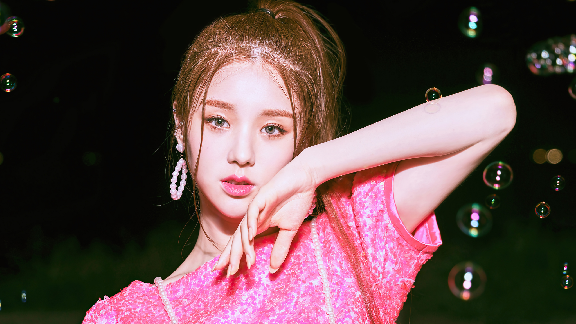


imshow("images/heejin01.jpg", 'Border', 'tight', 'InitialMagnification', 15);

% imshow("images/heejin01.jpg", 'InitialMagnification', 15);

Upstream Branch with Virtual Loads aka Virtual Loads Area (VLA)

branchDataUpStream = [
    1    3    0.00744    0.0372    0.0775    250    250    250    0    0    1    -360    360;
    2    4    0.00744    0.0372    0.0775    250    250    250    0    0    1    -360    360;
    3    4    0.01272    0.0636    0.1275    250    250    250    0    0    1    -360    360;
    ];
numBranchUpStream = size(branchDataUpStream, 1);

branchTableUpStream = array2table(branchDataUpStream(:, 1:5));
varNamesBranchData = ["fbus", "tbus", "R", "X", "B"];
branchTableUpStream.Properties.VariableNames = varNamesBranchData

branchTableUpStream = 3×5 table
    fbus    tbus       R         X         B   
    ____    ____    _______    ______    ______

     1       3      0.00744    0.0372    0.0775
     2       4      0.00744    0.0372    0.0775
     3       4      0.01272    0.0636    0.1275



[ybusUpStream, BMatrixUpStream, bUpStream, AUpStream] = ...
    ybusGenerator(busTable, branchTableUpStream, ...
    N, numBranchUpStream, disableTaps);

ybusUpStreamTable = array2table(ybusUpStream, ...
    "RowNames", ["5", "6", "3", "4"], "VariableNames", ["5", "6", "3", "4"]);
BMatrixUpStream = BMatrixUpStream([1 2 4], [1 2 4]);
BMatrixUpStreamTable = array2table(BMatrixUpStream, ...
    "RowNames", ["5", "6", "4"], ...
    "VariableNames", ["5", "6", "4"])

BMatrixUpStreamTable = 3×3 table
           5          6          4   
         ______    _______    _______

    5    26.882          0          0
    6         0     26.882    -26.882
    4         0    -26.882     42.605



AUpStreamTable = array2table(AUpStream, ...
    "RowNames", ["5-3", "6-4", "3-4"], "VariableNames", ["5", "6", "3", "4"])

AUpStreamTable = 3×4 table
           5    6    3     4 
           _    _    __    __

    5-3    1    0    -1     0
    6-4    0    1     0    -1
    3-4    0    0     1    -1


bUpStreamTable = array2table(bUpStream, ...
    "RowNames", ["5-3", "6-4", "3-4"], ...
    "VariableNames", ["5-3", "6-4", "3-4"])

bUpStreamTable = 3×3 table
            5-3       6-4       3-4  
           ______    ______    ______

    5-3    26.882         0         0
    6-4         0    26.882         0
    3-4         0         0    15.723


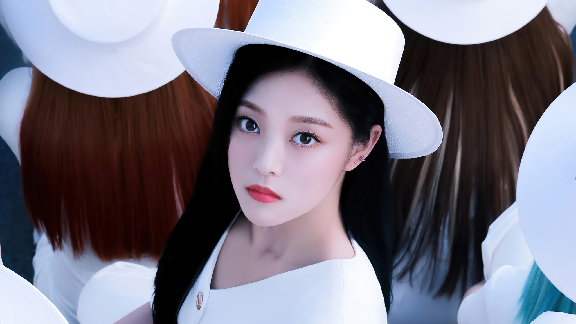


imshow("images/hyunjin01.jpg", 'Border', 'tight', 'InitialMagnification', 15);

Donwstream Branch with Virtual Generators aka Virtual Generator Area (VGA)

branchDataDownStream = [
    1    2    0.01008    0.05040   0.1025    250    250    250    0    0    1    -360    360;
    1    3    epsilon    epsilon   0.0775    250    250    250    0    0    1    -360    360;
    2    4    epsilon    epsilon   0.0775    250    250    250    0    0    1    -360    360;
    ];
numBranchDownStream = size(branchDataDownStream, 1);

branchTableDownStream = array2table(branchDataDownStream(:, 1:5));
varNamesBranchData = ["fbus", "tbus", "R", "X", "B"];
branchTableDownStream.Properties.VariableNames = varNamesBranchData

branchTableDownStream = 3×5 table
    fbus    tbus       R         X         B   
    ____    ____    _______    ______    ______

     1       2      0.01008    0.0504    0.1025
     1       3        0.001     0.001    0.0775
     2       4        0.001     0.001    0.0775



[ybusDownStream, BMatrixDownStream, bDownStream, ADownStream] = ...
    ybusGenerator(busTable, branchTableDownStream, ...
    N, numBranchDownStream, disableTaps);

ybusDownStreamTable = array2table(ybusDownStream, ...
    "RowNames", ["1", "2", "5'", "6'"], "VariableNames", ["1", "2", "5'", "6'"]);
BMatrixDownStream = BMatrixDownStream([1 2 4], [1 2 4]);
BMatrixDownStreamTable = array2table(BMatrixDownStream, ...
    "RowNames", ["1", "2", "6'"], ...
    "VariableNames", ["1", "2", "6'"])

BMatrixDownStreamTable = 3×3 table
             1          2        6'  
          _______    _______    _____

    1      1019.8    -19.841        0
    2     -19.841     1019.8    -1000
    6'          0      -1000     1000



ADownStreamTable = array2table(ADownStream, ...
    "RowNames", ["1-2", "1-5'", "2-6'"], "VariableNames", ["1", "2", "5'", "6'"])

ADownStreamTable = 3×4 table
            1    2     5'    6'
            _    __    __    __

    1-2     1    -1     0     0
    1-5'    1     0    -1     0
    2-6'    0     1     0    -1


bDownStreamTable = array2table(bDownStream, ...
    "RowNames", ["1-2", "1-5'", "2-6'"], ...
    "VariableNames", ["1-2", "1-5'", "2-6'"])

bDownStreamTable = 3×3 table
             1-2      1-5'    2-6'
            ______    ____    ____

    1-2     19.841       0       0
    1-5'         0    1000       0
    2-6'         0       0    1000


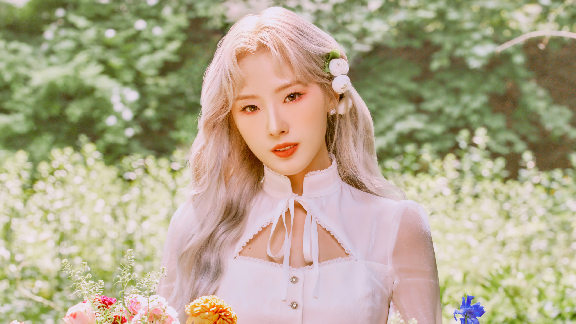


imshow("images/haseul01.jpg", 'Border', 'tight', 'InitialMagnification', 15);

Solving for Distributed Power Flow

PSpecUpStreamTable = 3×1 table
         PSpecUpStream
         _____________

    5           0     
    6           0     
    4        -0.8     


deltaFullUpStreamTable = 4×1 table
          delta  
         ________

    5           0
    6    -0.05088
    3           0
    4    -0.05088


PLUpStreamTable = 3×1 table
               PL    
           __________

    5-3             0
    6-4    4.4409e-16
    3-4           0.8


PSpecDownStreamTable = 3×1 table
          PSpecDownStream
          _______________

    1          -0.5      
    2          -1.7      
    6'            0      


deltaFullDownStreamRelativeTable = 4×1 table
           delta  
          ________

    1      -0.0022
    2     -0.08788
    5'           0
    6'    -0.08788


deltaFullDownStreamTable = 4×1 table
           delta  
          ________

    1      -0.0022
    2     -0.08788
    5'           0
    6'    -0.05088


PLDownStreamTable = 3×1 table
             PL 
            ____

    1-2      1.7
    1-5'    -2.2
    2-6'     -37


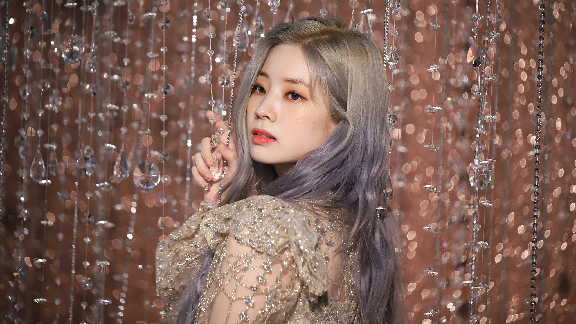

PSpecUpStreamTable = 3×1 table
         PSpecUpStream
         _____________

    5        -2.2     
    6         -37     
    4        -0.8     


deltaFullUpStreamTable = 4×1 table
          delta  
         ________

    5    -0.08184
    6     -3.7805
    3           0
    4     -2.4041


PLUpStreamTable = 3×1 table
            PL 
           ____

    5-3    -2.2
    6-4     -37
    3-4    37.8


deltaFullDownStreamRelative =    -0.0022
   -0.0879
         0
   -0.0879


deltaFullDownStreamRelativeTable = 4×1 table
           delta  
          ________

    1      -0.0022
    2     -0.08788
    5'           0
    6'    -0.08788


deltaFullDownStreamTable = 4×1 table
           delta  
          ________

    1     -0.08404
    2     -0.16972
    5'    -0.08184
    6'     -3.7805


PLDownStreamTable = 3×1 table
              PL  
            ______

    1-2        1.7
    1-5'      -2.2
    2-6'    3610.8


%How do we take care of two different slack buses if we're using the same
%set of theta values
%Upstream data is updated with 
for iter = 1:1
    if iter == 1
        PSpecUpStream = [0, 0, -0.80]'; %PSpec(i) = P_G(i) - P_L(i)
        PSpecUpStreamTable = array2table(PSpecUpStream, "RowNames", ["5", "6", "4"])
        deltaUpStream = BMatrixUpStream\PSpecUpStream; %BMatrix elements are negative of ybus elements
        deltaFullUpStream = [deltaUpStream(1:2); 0; deltaUpStream(end)];
        deltaFullUpStreamTable = array2table(deltaFullUpStream, ...
            "VariableNames", ["delta"], "RowNames", ["5", "6", "3", "4"])
        theta5 = deltaFullUpStream(1);
        theta6 = deltaFullUpStream(2);
        PLUpStream = bUpStream*AUpStream*deltaFullUpStream;
        PLUpStreamTable = array2table(PLUpStream, ...
            "RowNames", bUpStreamTable.Properties.RowNames, ...
            "VariableNames", ["PL"])  

        PSpecDownStream = [-0.5, -1.70, 0.00]'; %PSpec(i) = P_G(i) - P_L(i)
        PSpecDownStreamTable = array2table(PSpecDownStream, "RowNames", ["1", "2", "6'"])
        deltaDownStream = BMatrixDownStream\PSpecDownStream; %BMatrix elements are negative of ybus elements
        deltaFullDownStreamRelative = [deltaDownStream(1:2); 0; deltaDownStream(end)];
        deltaFullDownStreamRelativeTable = array2table(deltaFullDownStreamRelative,...
            "RowNames", ["1", "2", "5'", "6'"], 'VariableNames', ["delta"])
        deltaFullDownStream  = deltaFullDownStreamRelative +  [ones(4, 1)*theta5];
        deltaFullDownStream(end) = theta6;
        deltaFullDownStreamTable = array2table(deltaFullDownStream, ...
            "VariableNames", ["delta"], "RowNames", ["1", "2", "5'", "6'"])
        PLDownStream = bDownStream*ADownStream*deltaFullDownStream;
        PLDownStreamTable = array2table(PLDownStream, ...
            "RowNames", bDownStreamTable.Properties.RowNames, ...
            "VariableNames", ["PL"])        
    end

    imshow("images/dahyun01.jpg", 'Border', 'tight', 'InitialMagnification', 7.50);
    PSpecUpStream(1) = PLDownStream(2); %PSpecUpStream(1) = -PLDownStream(2);
    PSpecUpStream(2) = PLDownStream(3); %PSpecUpStream(2) = -PLDownStream(3);
    PSpecUpStreamTable(:, :) = array2table(PSpecUpStream)
    deltaUpStream = BMatrixUpStream\PSpecUpStream;
    theta5 = deltaUpStream(1); %send to DS
    theta6 = deltaUpStream(2); %send to DS
    deltaFullUpStream(1:2) = deltaUpStream(1:2);
    deltaFullUpStream(end) = deltaUpStream(end);
    deltaFullUpStreamTable(:, :) = array2table(deltaFullUpStream)
    PLUpStream = bUpStream*AUpStream*deltaFullUpStream;
    PLUpStreamTable(:, :) = array2table(PLUpStream)

    deltaFullDownStreamRelative = [deltaDownStream(1:2); 0; deltaDownStream(end)]
    deltaFullDownStreamRelativeTable = array2table(deltaFullDownStreamRelative,...
        "RowNames", ["1", "2", "5'", "6'"], 'VariableNames', ["delta"])
    deltaFullDownStream  = deltaFullDownStreamRelative +  [ones(4, 1)*theta5];
    deltaFullDownStream(end) = theta6;
%     deltaFullDownStream = [deltaDownStream(1:2); 0; theta6] + [ones(4, 1)*theta5];
    deltaFullDownStreamTable(:, :) = array2table(deltaFullDownStream)
    PLDownStream = bDownStream*ADownStream*deltaFullDownStream;
    PLDownStreamTable(:, :) = array2table(PLDownStream)
end






toc;

Elapsed time is 884.598444 seconds.
